# Assignment #2: ECMS

## **Introduction**

This report documents the implementation and analysis of an **Equivalent Consumption Minimization Strategy (ECMS)** for a parallel Hybrid Electric Vehicle (HEV), developed as part of Assignment 2. The objective is to design a real-time energy management controller that minimizes fuel consumption over the WLTP standardized driving cycle while maintaining charge-sustaining operation, that means ensuring the battery state of charge at the end of the cycle remains within 1% of its initial value of 60%.

The work is structured as follows. The driving cycle and scaled vehicle data are first loaded and prepared. An equivalence factor *s,* the key tuning parameter of ECMS, which penalizes electrical energy use in fuel-equivalent terms, is then calibrated via a bisection algorithm that iteratively searches for the value of *s* the one that minimizes the terminal SOC deviation. A full forward simulation is subsequently run with the calibrated factor and the controller's SOC warning logic active. Finally, the results are analyzed through a set of operating-point maps, power profiles and mode-distribution plots, and the key performance indicators (fuel consumption, fuel economy, final SOC) are saved for submission.

## Group information

Group number: 46

Students:

- Matteo Canestrini, s349238

- Dennis Bettinsoli, s357720

- Simone Massucco, s357725

## Load the cycle and vehicle data

This section initialises the workspace and loads all data required for the simulation. The WLTP driving cycle is imported and its speed profile converted from km/h to m/s; the acceleration array is used directly as provided. Vehicle parameters are loaded from `vehData.mat` and scaled to the target vehicle configuration (118 000 N gross weight, 27 000 N kerb weight, 2100 kg inertia) using the `scaleVehData` utility. Transmission control maps are loaded last, as they are consumed internally by the HEV plant model.

clear
close all
clc
addpath(genpath(fullfile("..", "Common")));

% Initialization
mission = load("WLTP.mat");                 % import the driving mission (WLTP)        
vehSpd = mission.speed_km_h ./ 3.6;         % vehicle speed in (m/s)
vehAcc = mission.acceleration_m_s2;         % vehicle acceleration in (m/s^2)
time = mission.time_s;                      % mission time in (s)

veh = load("vehData.mat");                      % import the vehicle data
veh = scaleVehData(veh,118000,27000,2100);      % scale the data


## Equivalence factor calibration

This section is dedicated to finding the optimal equivalence factor ( $s$ ) required to achieve a charge-sustaining strategy over the WLTP cycle. The calibration is performed by the `runSim` function (detailed at the end of this script), which employs a bisection algorithm to minimize the SOC deviation between the beginning and the end of the mission.

Running the bisection algorithm successfully converges after 9 steps, achieving a final SOC deviation of -0.0011. The resulting optimal equivalence factor is $s = 2.5645$.

[Soc_dev, s_calibrated] = runSim(time, vehSpd, vehAcc, veh)

Pre-check: s_low = 1.4 || SOC_dev = -0.17 
Pre-check: s_high = 3.6 || SOC_dev = 1.42 
Step = 1 | s_mid = 2.5000 | Soc_dev = -0.1682 
Step = 2 | s_mid = 3.0500 | Soc_dev = 1.0015 
Step = 3 | s_mid = 2.7750 | Soc_dev = 0.6002 
Step = 4 | s_mid = 2.6375 | Soc_dev = 0.2691 
Step = 5 | s_mid = 2.5688 | Soc_dev = 0.0153 
Step = 6 | s_mid = 2.5344 | Soc_dev = -0.1444 
Step = 7 | s_mid = 2.5516 | Soc_dev = -0.0642 
Step = 8 | s_mid = 2.5602 | Soc_dev = -0.0307 
Step = 9 | s_mid = 2.5645 | Soc_dev = -0.0011 
Successful calibration


Soc_dev = -0.0011

s_calibrated = 2.5645

## Run a simulation with the calibrated equivalence factor

Once the calibrated equivalence factor is obtained, a full simulation of the WLTP cycle is executed. To ensure strict computational efficiency, the SOC, optimal gear, optimal split factor and the equivalent fuel consumption are properly preallocated for post-processing. The simulation initializes the battery SOC at 60% and sets the *controller* flag to 1, to enable the warnings within the ECMS function.

 At each time step *n* the ECMS controller is called with the current vehicle speed, acceleration and battery SOC; it returns the optimal gear number γ and torque-split factor α. These are fed into the HEV plant model `hev_cell_model`, which advances the SOC and returns stage cost, feasibility flag, and the four power-profile structures (engine, e-machine, battery, vehicle). 

Finally, upon completing the driving cycle, the script leverages the *min* function to identify the absolute minimum equivalent fuel consumption and its corresponding gear and split factor.

% --- MAIN SIMULATION LOOP ---

% Preallocation arrays
SOC_sim = zeros(length(time) + 1, 1);
gamma_opt_array = zeros(length(time), 1);
alpha_opt_array = zeros(length(time), 1);
mf_eq = zeros(length(time), 1);


% Initialize the simulation parameters
controller = 1;                          % Activate controller to raise warnings
SOC_sim(1) = 0.6;                        % Initial battery state of charge ( 60% )

% Main loop
for n = 1:length(time)

    % Get the optimal gamma and alpha values from ECMS_controller
    [gamma_opt,alpha_opt,mf_opt] = ECMS_controller(vehAcc(n), vehSpd(n), SOC_sim(n), veh, s_calibrated, controller);

    [x_next, stageCost, unfeas, engPrf(n), emPrf(n), battPrf(n),vehPrf(n)] = hev_cell_model({SOC_sim(n)}, {gamma_opt,alpha_opt}, {vehSpd(n),vehAcc(n)}, veh); 
    
    % Update state of charge
    SOC_sim(n+1) = x_next{1};

    mf_eq(n) = mf_opt;

    % Store the optimal gear number and torque-split factor for post-processing analysis
    gamma_opt_array(n) = gamma_opt;
    alpha_opt_array(n) = alpha_opt;


end

[min_cost, idx] = min(mf_eq);

% gear number that minimize mf_eq
gamma_min = gamma_opt_array(idx); 

% engine torque-split factor that minimize mf_eq
alpha_min = alpha_opt_array(idx);      


## Save results

After the main simulation loop, the collected data arrays are reorganized into scalar structures to facilitate data manipulation and plotting. All four profiles are then packed into a single structure called *prof.*

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.
engPrf = structArray2struct(engPrf);
emPrf = structArray2struct(emPrf);
battPrf = structArray2struct(battPrf);
vehPrf = structArray2struct(vehPrf);

% Pack profiles into a single structure
prof.engPrf = engPrf;
prof.emPrf = emPrf;
prof.battPrf = battPrf;
prof.vehPrf = vehPrf;


## Results analysis

The following section provides a comprehensive analysis of the simulation results, by means of using various plots to illustrate the real-time energy management and behavior of the ECMS controller throughout the entire WLTP cycle.

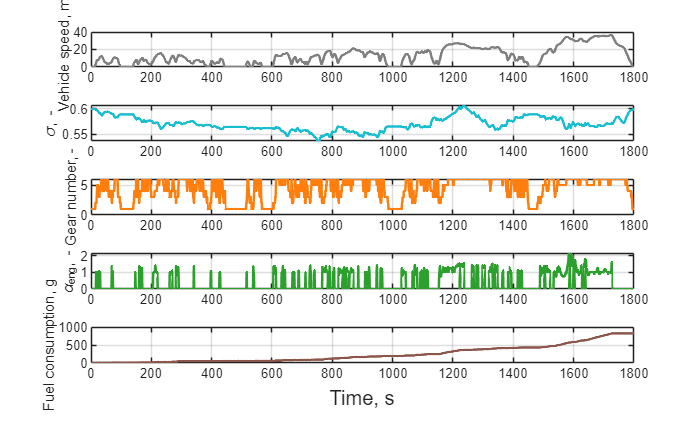

% Velocity, fuel consumption, SOC, gear profile
mainProfiles(prof);

The first figure presents the time-domain simulation profiles, specifically detailing the vehicle speed, SOC trajectory, gear number, torque-split factor, and cumulative fuel consumption.

- ***Vehicle Speed*** & ***Gear***: the vehicle accurately tracks the WLTP speed profile, with the gear frequently shifting to adapt to the speed and torque demands.

- ***SOC Trajectory*** ($\sigma$): the State of Charge (SOC) profile clearly demonstrates a strict charge-sustaining behavior. The battery is depleted during low-speed in urban phases, and recharged during braking (regenerative braking) and at high-speed cruising. Crucially, the final SOC smoothly returns to the initial reference value of $0.60$, validating the correct calibration of the ECMS equivalence factor ($s$).

- ***Torque Split Factor*** ($\alpha_{eng}$): the $\alpha_{eng}$ subplot highlights the controller's real-time energy management. When $\alpha_{eng} = 0$, the vehicle is in Pure Electric mode (engine off). Values between $0 < \alpha_{eng} < 1$ represent Power Split (e-machine assisting the engine). Peaks where $\alpha_{eng} > 1$ indicate Battery Charging mode, where the engine generates excess of torque to drive the e-machine as a generator.

- ***Fuel Consumption***: the cumulative fuel consumption grows smoothly, mostly flattening out during pure electric urban phases and rising steeper during high-speed extra-urban phases, reaching a final value of approximately 0.8 kg.

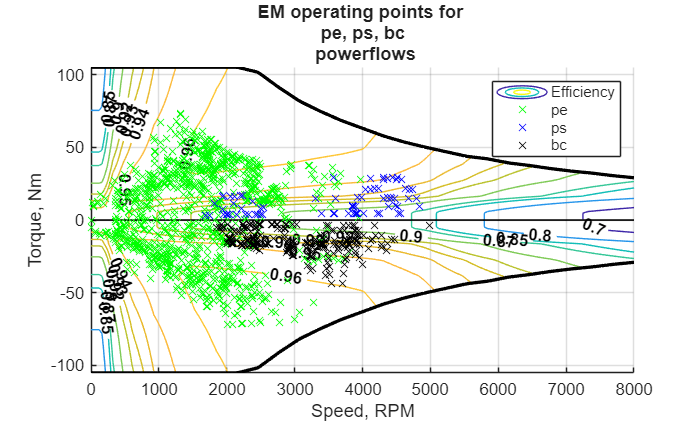


% Plot e-Machine operating points over its efficiency map
emMapWithPF(veh.em, prof);

This second figure, overlays the electric machine's (EM) operating points onto its efficiency contour map, categorized by the active power flows modes.

- ***Pure Electric*** (pe, green): during pure electric driving and regenerative braking, the EM operates across a wide spectrum of speeds and torques. Most points fall within the high-efficiency regions (above 0.90 to 0.96 efficiency).

- ***Battery Charging*** (bc, black): when the engine recharges the battery, the EM acts as a generator (negative torque). The ECMS strategically clusters these points in the highly efficient generator quadrant to minimize energy conversion losses.

- ***Power Split*** (ps, blue): the motor assist operations are relatively low but occur at high speeds (above 3300 rpm) and also between 1500 and 2500 rpm, providing crucial boosting power when the engine alone is insufficient or less efficient.

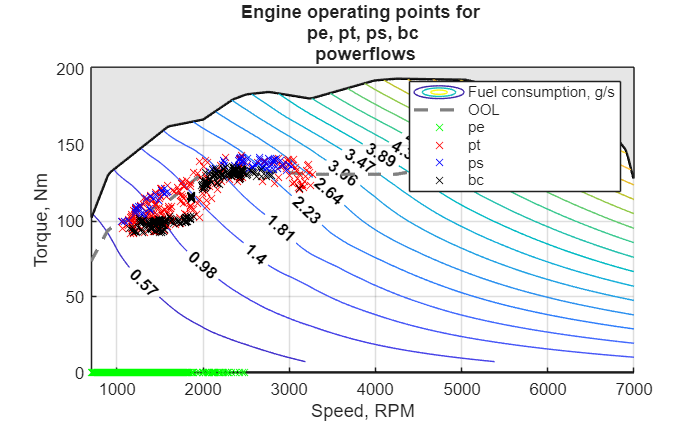


% Plot ICE operating points over the Fuel Consumption (FC) map 
engMapWithPF(veh.eng,prof,"fc","all");

This figure, depicts the Internal Combustion Engine (ICE) operating points overlaid on the fuel consumption (g/s) map. The most prominent feature of the ECMS controller is its ability to force the engine operating points (red, blue, and black markers) to cluster tightly along the dashed grey Optimal Operating Line (OOL). This proves that the ECMS successfully shifts the engine load to peak efficiency regions.

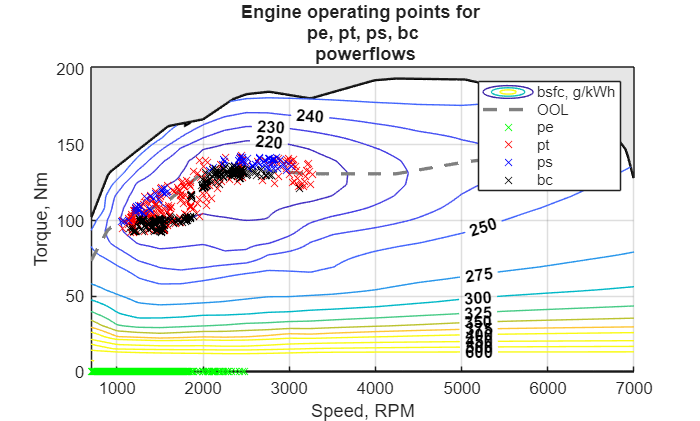


% Plot ICE operating points over the Brake Specific Fuel Consumption (BSFC) map
engMapWithPF(veh.eng,prof,"bsfc","all");

In this other figure, the ICE operating points overlaid on the Brake Specific Fuel Consumption (BSFC, g/kWh) map is depicted. During low-to-medium power demands where the engine would normally operate inefficiently, the ECMS increases the engine load ($\alpha_{eng} > 1$). This shifts the operating points upwards onto the OOL (around 220-230 g/kWh BSFC or 38% efficiency - see also figure below), generating vehicle propulsion while simultaneously recharging the battery.

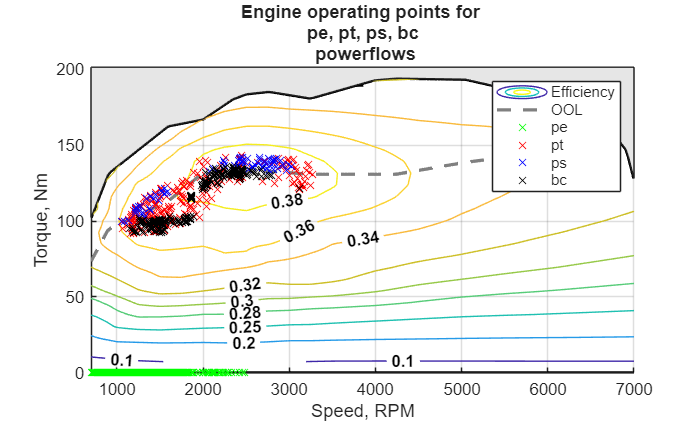


% Plot ICE operating points over the Efficiency (BSFC) map
engMapWithPF(veh.eng,prof,"eff","all");

Here, is shown the ICE operating points overlaid on the thermal efficiency map. The green markers correctly lie strictly on the zero-torque axis (0% efficiency), confirming that the engine is turned off or decoupled to avoid idling fuel penalties when the EM is handling the load. Furthermore, the ECMS controller ensures that all ICE operating points are maintained above a 36% thermal efficiency.

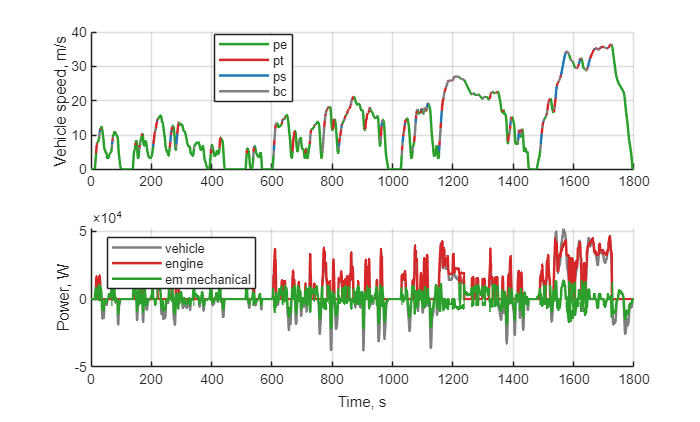


% Plot power profiles to inspect the 4 operating conditions
powerProfiles(prof);

These two charts detail the vehicle speed and the instantaneous power distribution, highlighting the mode selection throughout the simulation time. In particular:

- ***Speed Profile*** (*upper graph*): the color speed profile reveals the ECMS macroscopic strategy. Pure Electric mode (***green***) is heavily prioritized during the low-speed regions and during all deceleration phases (regenerative braking). Pure Thermal (***red***) and Battery Charging (***grey***) modes are primarily activated during the higher-speed extra-urban sections and in highway phases, where the ICE efficiency is inherently higher.

- ***Power Distribution*** (*lower graph*): the mechanical engine power (***red line***) shows the engine handling the baseline positive power demands during high-load and high-speed driving, and, if necessary, also at low vehicle speeds when the battery has low SOC. The EM (***green line***) dynamically intervenes to absorb negative power spikes (efficient kinetic energy recovery) and provides positive power assist during sharp transient accelerations where the engine supply would be costly in terms of fuel.

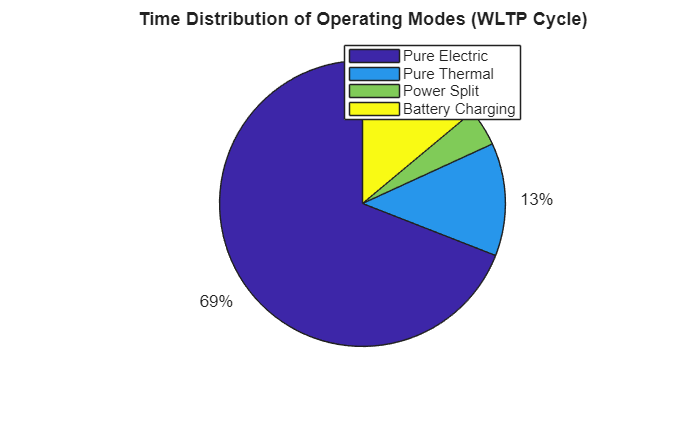


% EXTRA PLOT 1: Operating Modes Distribution
% Calculate the time spent in each operating mode by analyzing the 'engAlpha' array
% Count the number of seconds for each condition
time_PE = sum(alpha_opt_array == 0); % Pure Electric: alpha is exactly 0
time_PT = sum(alpha_opt_array == 1); % Pure Thermal: alpha is exactly 1
time_PS = sum(alpha_opt_array > 0 & alpha_opt_array < 1); % Power Split: alpha is between 0 and 1
time_BC = sum(alpha_opt_array > 1); % Battery Charging: alpha is strictly greater than 1

% Create the Pie Chart
figure
labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
% The pie function automatically calculates the percentages based on the given array
pie([time_PE, time_PT, time_PS, time_BC]);
legend(labels)
title('Time Distribution of Operating Modes (WLTP Cycle)');

This pie chart quantifies the time distribution of the powertrain operating modes over the mission. The ECMS strategy achieves a highly electrified profile:

- ***Pure Electric*** (***69%***): the vehicle operates in pure electric for the vast majority of the cycle time, maximizing the use of the EM in low-load conditions.

- ***Battery Charging*** (***14%***): this represents the active load-shifting strategy, where the engine is used to generate electrical energy at high efficiency.

- ***Pure Thermal*** (***13%***) & ***Power Split*** (***4%***): in pure ICE and power-split modes are strictly reserved for high-power demands, ensuring that the engine is only activated when it can operate near its Optimal Operating Line.

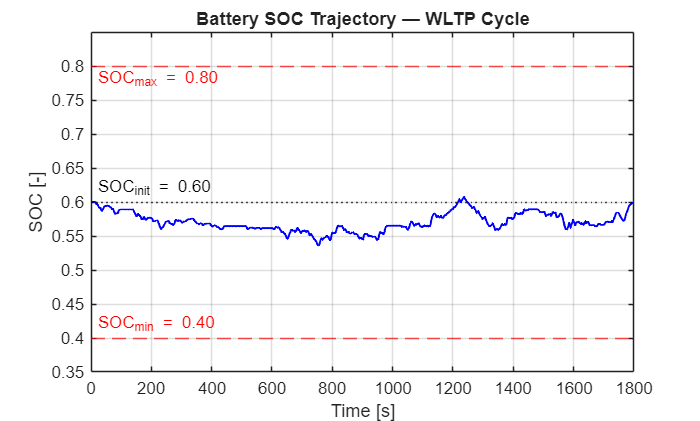


% EXTRA PLOT 2: SOC trajectory with operating limits
figure
plot(time, SOC_sim(1:end-1), 'b', 'LineWidth', 1.2)
yline(0.4, 'r--', 'SOC_{min} = 0.40', 'LabelHorizontalAlignment','left')
yline(0.8, 'r--', 'SOC_{max} = 0.80', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
yline(0.6, 'k:', 'SOC_{init} = 0.60', 'LabelHorizontalAlignment','left')
xlabel('Time [s]')
ylabel('SOC [-]')
ylim([0.35 0.85])
title('Battery SOC Trajectory — WLTP Cycle')
grid on

This last figure, provides a focused view of the SOC trajectory relative to the physical battery constraints ($SOC_{min
} = 0.40$, $SOC_{max} = 0.80$).

Starting from an initial reference of $SOC_{init} = 0.60$, the ECMS controller demonstrates excellent stability. The SOC fluctuates naturally between roughly 0.53 and 0.61, comfortably far from the critical boundaries, ensuring battery longevity and safety. The trajectory's perfect convergence back to the 0.60 target at $t = 1800$ s confirms that the ECMS cost function (via the equivalence factor) is perfectly balanced, achieving true charge-sustaining operation without penalizing drivability.

To conclude, a significant limit of this ECMS controller is explained.

As an instantaneous optimization algorithm, the standard ECMS evaluates the cost function at each time step without any preview of the future driving conditions. Consequently, while it achieves a near-optimal power split for the immediate instant, it cannot guarantee the absolute global optimum over the entire WLTP cycle. This is a structural limitation compared to global optimization algorithms, such as Dynamic Programming, which utilize the full cycle preview to establish the absolute minimum fuel consumption baseline.

## Store results

Scalar performance metrics are derived from the simulation arrays and saved to `results.mat`:

- `fuelConsumption` [kg], computed by trapezoidal integration of the engine fuel-flow rate over the cycle duration.

- `fuelEconomy` [l/100 km], is the fuel volume (mass divided by fuel density) normalised by the total distance travelled.

- `finalSOC, ``represents the b`attery SOC at the last time step, used to verify charge-sustaining compliance.

- `eqFactor,` is the calibrated equivalence factor s = 2.5645.

- `prof, ``is` the structure containing all four time-profile scalar structures.

The simulation results confirm the correct behaviour of the ECMS controller across the full WLTP cycle. The total distance covered is **23.27 km**, consistent with the official WLTP class 3 profile.

The total fuel consumption amounts to **0.82 kg**, corresponding to a fuel economy of **4.50 l/100 km**. This figure is significantly lower than a comparable conventional vehicle, which would typically consume between 8 and 12 l/100 km on the same cycle, demonstrating the effective fuel-saving potential of the hybrid powertrain managed by the ECMS strategy.

The final state of charge is **0.599**, deviating from the initial value of 0.600 by less than the prescribed 1% threshold. This confirms that the bisection calibration of the equivalence factor (*s* = 2.5645) successfully enforces charge-sustaining operation over the entire cycle, making the fuel consumption figure directly comparable between different energy management strategies without the confound of net battery energy usage.

It is worth noting that the fuel economy reported here represents the result of an offline calibration: the equivalence factor was tuned with full knowledge of the cycle. In a real-time deployment, the cycle is unknown in advance, and *s* would need to be estimated adaptively, which would generally yield slightly higher fuel consumption than the offline-optimised value reported here.


% 1. Calculate total fuel consumption in kg
fuelConsumption = trapz(time,engPrf.fuelFlwRate)/1000; 

% 2. Calculate TOTAL distance in km 
distance = trapz(time, vehSpd) / 1000; 

% 3. Calculate total fuel volume in liters
fuel_volume = fuelConsumption / veh.eng.fuelDensity;

% 4. Calculate fuel economy in l/100km
fuelEconomy = (fuel_volume / distance) * 100; 

% 5. Get final state of charge
finalSOC = SOC_sim(end); 

% 6. Get the equivalence factor s
eqFactor = s_calibrated;

% 7. Save results to .mat file
save("results.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC", "eqFactor");

% Calculate and display the total distance and fuel economy
fprintf('The total distance is: %.2f km\n', distance);

The total distance is: 23.26 km


fprintf('The amount of fuel consumed is: %.2f kg',fuelConsumption);

The amount of fuel consumed is: 0.82 kg

fprintf('Fuel Economy: %.2f l/100km\n', fuelEconomy);

Fuel Economy: 4.50 l/100km


fprintf('Final State of Charge: %.3f\n', finalSOC);

Final State of Charge: 0.599


fprintf('Optimal equivalence factor: %.4f\n', s_calibrated);

Optimal equivalence factor: 2.5645


## Equivalence factor calibration function

The runSim function executes a bisection algorithm to dynamically calibrate the equivalence factor ( $s$ ) for the ECMS strategy. The objective of this calibration is to ensure a strictly charge-sustaining operation over the entire driving cycle. 

Before the bisection loop runs, the function verifies that `s_low` and `s_high` actually bracket the solution. It does this by simulating a full driving cycle at each bound and checking that the resulting SOC deviations have opposite signs — one positive, one negative. This is the necessary condition for bisection to work: if both bounds push the SOC in the same direction, there is no guarantee the charge-sustaining `s` lies in that interval, and the algorithm may never converge. If the condition fails, the function throws an error immediately rather than running 15 useless iterations.

The function receives as input the driving mission arrays ( $time$, $vehSpd$, $vehAcc$ ) and the vehicle data structure ( $veh$ ). As output, it delivers the optimal equivalence factor ( *s_calibrated *) and the final deviation of battery state of charge ( *Soc_dev *).

The algorithm is designed to find a root of the function $\Delta{SOC}(s) \approx 0$, where:

$\Delta{SOC}(s) = \sigma(t_f) - \sigma(t_0)$, with an initial state of charge of $\sigma(t_0) = 0.6$ ( 60% ).

To achieve this, the method iteratively halves the search interval *[a,b]* defined by an initial lower bound ( $s_{low} = 1.4$ ) and an upper bound ( $s_{high} = 3.6 ). Before the bisection loop begins, a rigorous pre-check is performed to verify that $\Delta{SOC}(s_{low})$ and $\Delta{SOC}(s_{high})$ possess opposite signs. A dedicated local function, `evaluateSocdev`, simulates a full driving cycle at each boundary to extract the resulting terminal SOC deviations. This function receives as input the driving mission arrays ( $time$, $vehSpd$, $vehAcc$ ), the vehicle data structure ( $veh$ ), a specific equivalence factor $s$ and the controller flag ( set to 0 to suppress warnings), whereas as output the SOC deviation of the two initial bounds. 

 Therefore, once the pre-checks are satisfied, the algorithm, at each iteration, tests the mid-point ( $s_{mid}$ ) by running a full simulation of the driving cycle. A dedicated boolean flag ( $controller = 0$ ) is passed to the ECMS_controller to temporarily suppress warnings during this calibration phase. 

The iteration process continues until the absolute deviation falls within the accepted tolerance ( $tolerance = 0.01$ ), meaning the final SOC is successfully constrained between 0.59 < $\sigma_f$ < 0.61. Prior to entering the iteration process, the *SOC_dev* variable is initialized to an arbitrarily large value ( *1000 *), in order to exceed the tolerance and to guarantee the execution of the first calibration step within the *while *loop. Furthermore, to guarantee computational safety and avoid infinite loops, it is included a limit of maximum iterations ( *max_step *= 15 ). Once the tolerance is achieved, the function triggers an early exit ( *return *) and outputs the calibrated equivalence factor, correspond to the mid-point ( $s_{calibrated} = s_{mid}$ ). 

After the simulation, if tolerance has not been achieved, the SOC deviation is evaluated: 

- if ***SOC_dev *****< 0**: the battery has been depleted. This indicates that the current equivalence factor under-penalizes electrical energy consumption, leading the controller to over-utilize the battery. Consequently, the lower bound is updated ( $s_{low} = s_{mid}$ ) to tighten the interval and to increase the equivalence factor in the next step.

- if ***SOC_dev *****> 0**: the battery has been overcharged, so the upper bound is updated ( $s_{high} = s_{mid}$ ), to decrease the mid-point in the next step. 

Naturally, in both cases, the boundary updates only occur if the absolute SOC deviation still exceeds the predefined tolerance

function [Soc_dev, s_calibrated] = runSim(time, vehSpd, vehAcc, veh)

% RUNSIM 
% Executes a bisection algorithm to calibrate the equivalence 
% factor 's' for the ECMS strategy.
% 
% INPUT Arguments:
%   time   : double - time array of the driving cycle [s]
%   vehSpd : double - current vehicle speed [m/s]
%   vehAcc : double - current vehicle acceleration  [m/s^2]
%   veh    : struct - vehicle data structure 
% 
% OUTPUT Arguments:
%   Soc_dev      : double - Final Battery State of Charge deviation (SOC_end - SOC_initial)
%   s_calibrated : double - The optimal equivalence factor found by the algorithm

    s_high = 3.6;                      % Upper bound for the equivalence factor
    s_low = 1.4;                     % Lower bound for the equivalence factor
    s_mid = (s_high + s_low)/2;      % First mid point of bisection algorithm
    controller = 0;                  % Deactivate controller for calibration

    tolerance = 0.01;                % Max allowed SOC deviation ( 1% )
    Soc_dev = 1000;
    step = 1;
    max_step = 15;

    % PRECHECK 
    % Bisection is valid only if f(s_low) and f(s_high) have opposite signs,
    % i.e. the zero-crossing (charge-sustaining s*) lies inside [s_low, s_high].
    % Run one full simulation at each bound and verify the sign condition.

    Soc_dev_low = evaluateSocdev(vehAcc, vehSpd, s_low, veh, time, controller);
    Soc_dev_high = evaluateSocdev(vehAcc, vehSpd, s_high, veh, time, controller);

    fprintf('Pre-check: s_low = %.1f || SOC_dev = %.2f \n', s_low, Soc_dev_low);
    fprintf('Pre-check: s_high = %.1f || SOC_dev = %.2f \n', s_high, Soc_dev_high);
    
    if sign(Soc_dev_low) == sign(Soc_dev_high)
        error('runSim: invalidBounds: s_low (%.1f) and s_high (%.2f) yield SOC deviations of the same sign (%.4f, %.4f).\n',s_low,s_high,Soc_dev_low,Soc_dev_high)
    end

    while abs(Soc_dev) > tolerance && step <= max_step
        % Preallocation of SOC array to store the soc deviation
        Soc_sim = zeros(length(time) + 1, 1);     
        Soc_sim(1) = 0.6;                          % Initial SOC condition ( 60% )

        for n = 1:length(time)

            [gamma_opt, alpha_opt, ~] = ECMS_controller(vehAcc(n), vehSpd(n), Soc_sim(n), veh, s_mid, controller);
            [x_next, ~, ~, ~, ~, ~, ~] = hev_cell_model({Soc_sim(n)}, {gamma_opt, alpha_opt}, {vehSpd(n), vehAcc(n)}, veh);
            Soc_sim(n+1) = x_next{1};

        end

        % Compute SOC deviation
        Soc_dev = Soc_sim(end)- Soc_sim(1);
        fprintf('Step = %d | s_mid = %.4f | Soc_dev = %.4f \n', step, s_mid, Soc_dev);

        if abs(Soc_dev) <= tolerance              % Tolerance achieved
            s_calibrated = s_mid;
            disp('Successful calibration');
            return
        end

        % Examine sign of SOC deviation in order to replace the boundaries
        if Soc_dev < 0
            s_low = s_mid;    % Update lower bound
        else
            s_high = s_mid;   % Update upper bound
        end

        s_mid = (s_high + s_low) / 2;   % Recalculate mid-point
        step = step + 1;
    end

    s_calibrated = s_mid;

    if abs(Soc_dev) > tolerance
    warning('Bisection did not converge within %d iterations. Final SOC deviation: %.4f. Consider widening [s_low, s_high] or increasing max_step.', max_step, Soc_dev);
    end

end


function Soc_dev = evaluateSocdev(vehAcc, vehSpd, s, veh, time, controller)
    Soc_sim = zeros(length(time) + 1, 1);
    Soc_sim(1) = 0.6;

    for k = 1:length(time)

        % Get the optimal gamma and alpha values from ECMS_controller
        [gamma_opt_test,alpha_opt_test, ~] = ECMS_controller(vehAcc(k), vehSpd(k), Soc_sim(k), veh, s, controller);
        [x_next_test, ~, ~, ~, ~, ~, ~] = hev_cell_model({Soc_sim(k)}, {gamma_opt_test,alpha_opt_test}, {vehSpd(k),vehAcc(k)}, veh); 
        
        % Update state of charge
        Soc_sim(k+1) = x_next_test{1};

    end
    Soc_dev = Soc_sim(end)-Soc_sim(1);
end

## The ECMS controller

The ECMS controller implements a single time-step optimal control for a parallel Hybrid Electric Vehicle (HEV) using the *Equivalent Consumption Minimization Strategy (ECMS)*. 

The function receives as inputs the vehicle acceleration ($vehAcc$) and the vehicle speed ($vehSpd$) during the cycle, the current SOC of battery ($SOC$), the data regarding the vehicle structure ($veh$), the calibrated equivalence factor ($s$) and a boolean flag ($controller$) used to manage the activation of specific warnings during the simulation.

As output, it provides the optimal gear number ( *gamma_opt *), the optimal engine torque-split factor ( *alpha_opt *) and the optimal value of equivalent fuel consumption ( *mf_dot *) at that specific time step. 

At each call the function sweeps a discrete grid of gear numbers (between 1 and 6) and torque-split factors (51 uniform points from 0 to 2.5). The $\alpha_{eng}$ array was specifically designed with 51 points to ensure a precise step of 0.05. This choice guarantees that all fundamental HEV operating modes are perfectly targeted:

- **Pure electric**: $\alpha = 0$

- **Power Split**:  0 < $\alpha$ < 1

- **Pure Thermal**: $\alpha = 1.0$

- **Battery Charging**: $\alpha$ > 1

The controller evaluates the HEV plant model for every ($\gamma$ , $\alpha$) combination simultaneously through a fully vectorized approach. This parallel evaluation is enabled by the architecture of the function `hev_cell_model`, which accepts cell arrays as inputs. This feature allows the model to process the entire grid of combinations in a single function call. Consequently, this implementation avoids the use of iterative loops, reducing the computational time. Then, the function computes the equivalent fuel-mass flow rate for every pair of ( $\gamma$, $\alpha$):   

$m_{eq} = \dot{m_f} -  \frac{s \cdot E_{bat} }{ Q_{lhv}} \cdot \dot{SOC}$  [g/s]

where *s* is the calibrated equivalence factor that converts electrical power into a fuel rate. To guarantees strict dimensional consistency within this formula, careful unit conversions are performed: the nominal battery energy $E_{bat}$ is scaled into Joules ( $J$ ), and the fuel Lower Heating Value $Q_{lhv}$ is converted into $J/g$. Furthermore, the derivatives of both State of Charge ( $\dot{SOC}$ ) and the fuel-mass flow rate ( $\dot{m_f}$ ) are computed to correctly evaluate the equivalent fuel-mass flow rate.

Unfeasible operating points (flagged by the HEV model) and SOC excursions outside [0.40, 0.80] are discouraged via a large additive penalty (10⁶) applied directly to the vectorized cost matrix.

Finally, the function employs the $min$ function to locate the absolute minimum equivalent consumption within the cost matrix. The resulting linear index is then translated into matrix coordinates using the $ind2sub$ function. This procedure allows to return the optimal gear *gamma_opt,* torque-split factor *alpha_opt *and the optimal equivalent fuel consumption *mf_opt*, ready for the drive-cycle simulation loop.

function [gamma_opt, alpha_opt, mf_opt] = ECMS_controller(vehAcc, vehSpd, SOC, veh, s, controller)

% ECMS_CONTROLLER
% Evaluate the optimal gear number and optimal torque-split factor to
% minimize the equivalence fuel consumption in a single time step.
%
% INPUT Arguments:
%   vehAcc     : double - current vehicle acceleration  [m/s^2] 
%   vehSpd     : double - current vehicle speed [m/s] 
%   SOC        : double - current battery State of Charge [-]
%   veh        : struct - vehicle data structure 
%   s          : double - equivalence factor for electrical energy [-]
%   controller : double - logical flag: 1 = warnings active, 0 = suppressed
%
% OUTPUT Arguments:
%   gamma_opt : double - optimal gear number (1 to 6)
%   alpha_opt : double - optimal engine torque-split factor (0 to 2.5)
%   mf_opt    : double - minimum equivalent fuel consumption [g/s]

% Control grid
gamma = 1:6;                                  % possible gear numbers
alpha = linspace(0, 2.5, 51);                 % possible torque-split factors (step = 0.05)
[gamma_k, alpha_k] = ndgrid(gamma, alpha);    % full combination grid [6 x 51]

% Constants (computed once per call)
E_bat = veh.batt.nomEnergy * 3600;            % nominal battery energy [J]
Q_lhv = veh.eng.fuelLHV / 1000;               % fuel lower heating value [J/g]

% SOC operating limits
SOC_min = 0.4;
SOC_max = 0.8;

% Penalty value for infeasible and out-of-bounds operating points
penalty = 1e6;

% vectorized evaluation of all (gamma, alpha) combinations

[x_next_all, stageCost_all, unfeas_all] = hev_cell_model({SOC}, {gamma_k, alpha_k}, {vehSpd, vehAcc}, veh);

SOC_next_all = x_next_all{1};                          % [6 x 51], SOC at next step

% vectorized cost computation
SOC_dot_all  = (SOC_next_all - SOC) / veh.dt;          % SOC rate of change [1/s]
mf_dot_all   = stageCost_all / veh.dt;                 % fuel flow rate [g/s]

% Equivalent fuel consumption for every (gamma, alpha) pair [g/s]
CostMatrix = mf_dot_all - (s * E_bat / Q_lhv) * SOC_dot_all;

% vectorized penalty application
% Infeasible powertrain operating points
CostMatrix(unfeas_all) = CostMatrix(unfeas_all) + penalty;

% SOC out of bounds (cumulative with infeasibility penalty if both violated)
SOC_violation = SOC_next_all < SOC_min | SOC_next_all > SOC_max;
CostMatrix(SOC_violation) = CostMatrix(SOC_violation) + penalty;

% Optimal control selection
[mf_opt, idx_min] = min(CostMatrix, [], 'all');
[gamma_idx, alpha_idx] = ind2sub(size(CostMatrix), idx_min);

gamma_opt = gamma(gamma_idx);
alpha_opt = alpha(alpha_idx);

% warnings only on the selected optimal point

if controller == 1
    SOC_next_opt = SOC_next_all(gamma_idx, alpha_idx);

    if SOC_next_opt < SOC_min
        warning('SOC (%.3f) is below the lower threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_min);
    elseif SOC_next_opt > SOC_max
        warning('SOC (%.3f) exceeds the upper threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_max);
    end

    if vehSpd < 0
        warning('Negative vehicle speed: controller is implemented for forward motion only.');
    end
end

end